# Improving Predictive Models

## 1. Cross Validation

Use 10-fold cross validation to evaluate the various predictive models for the heart disease data.

% Run comparison with holdout validation
compareclassifiers

                                     ResubLoss     Loss  
                                     _________    _______

    kNN                                     0     0.34127
    kNN k=5                           0.22222     0.24713
    Weighted kNN k=5                        0     0.24713
    Tree                             0.078947     0.28237
    Pruned tree                       0.14035     0.20004
    Tree (all predictors)            0.055556     0.23531
    Pruned tree (all predictors)      0.10819     0.21179
    NB                                0.29825     0.20002
    NB kernel                         0.26023      0.1765
    NB (all predictors)               0.20468     0.11767
    NB kernel (all predictors)        0.19591      0.1412
    Linear DA                         0.27193      0.1765
    Quadratic DA                      0.24854      0.2706
    Linear SVM                        0.30117     0.16475
    Gaussian SVM                      0.26023     0.16473
    Linear SV

% Add variable to hold cross validation errors
results.kFoldLoss = zeros(height(results),1);

% Remove pruned trees because the cross validation cannot apply for the pruned trees
results([5 7],:) = []

results = 15×3 table
                                     ResubLoss     Loss      kFoldLoss
                                     _________    _______    _________

    kNN                                     0     0.34127        0    
    kNN k=5                           0.22222     0.24713        0    
    Weighted kNN k=5                        0     0.24713        0    
    Tree                             0.078947     0.28237        0    
    Tree (all predictors)            0.055556     0.23531        0    
    NB                                0.29825     0.20002        0    
    NB kernel                         0.26023      0.1765        0    
    NB (all predictors)               0.20468     0.11767        0    
    NB kernel (all predictors)        0.19591      0.1412        0    
    Linear DA                         0.27193      0.1765        0    
    Quadratic DA                      0.24854      0.2706        0    
    Linear SVM                        0.30117     0.164

% Make a cross validation partition
rng(1234)
part=cvpartition(heartdataNum.HeartDisease,'KFold',10)

part = K-겹 교차 검증 분할
   NumObservations: 427
       NumTestSets: 10
         TrainSize: 385  384  384  384  384  384  384  384  385  385
          TestSize: 42  43  43  43  43  43  43  43  42  42

### 1.1. Create cross-validated models

Note that the cross-validated models are only used to evaluate performance. The fitted models do not have a `predict` method. 

% Divide the data into training+validation and test sets
rng(1234)
part=cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2);
trValidx=training(part);
trValData=heartdataNum(trValidx,:);% trValData is to build a model
testData=heartdataNum(~trValidx,:);% Assume that testData is newly measured data.

% Divide the training+validation data into training and validation sets
part1=cvpartition(trValData.HeartDisease,'HoldOut',0.2)

part1 = 홀드아웃 교차 검증 분할
   NumObservations: 342
       NumTestSets: 1
         TrainSize: 274
          TestSize: 68

tridx=training(part1);
trData=trValData(tridx,:);
valData=trValData(~tridx,:);

% Models with 'holdout' do have a predict method for the validation data
mdlknn=fitcknn(trData,'HeartDisease');
errKNN_tr=resubLoss(mdlknn)

errKNN_tr = 0

errKNN_val=loss(mdlknn,valData)

errKNN_val = 0.4130

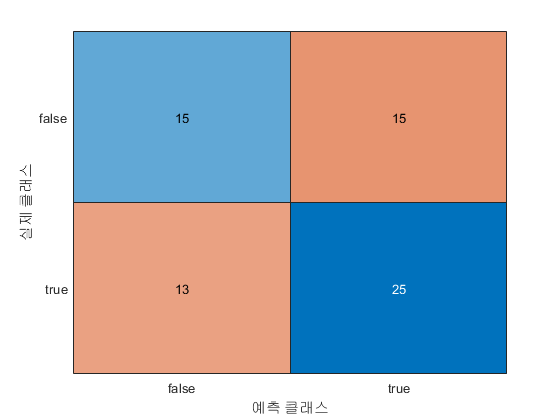

HDpred_val=predict(mdlknn,valData);
HDtrue_val=valData.HeartDisease;
figure
confusionchart(HDtrue_val,HDpred_val)

% Models with 'holdout' do have a predict method for the test data
HDpred_test=predict(mdlknn,testData)

HDpred_test = 85×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 



% k-fold
part2=cvpartition(trValData.HeartDisease,'KFold',10);
mdlknn_kfold=fitcknn(trValData,'HeartDisease','CVPartition',part2)

mdlknn_kfold =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {'Age'  'Cholesterol'  'ExerciseDuration'  'METs'  'RestingHeartRate'  'RestingSystolic'  'RestingDiastolic'  'MaxHeartRate'  'PeakExSystolic'  'PeakExDiastolic'  'InducedSTDep'}
           ResponseName: 'HeartDisease'
        NumObservations: 342
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: [false    true]
         ScoreTransform: 'none'


  Properties, Methods


errKNN_kfold=kfoldLoss(mdlknn_kfold)

errKNN_kfold = 0.3655

% Models with 'kfold' do NOT have a predict method
% HDpred_test_kfold = predict(mdlknn_kfold,testData)

함수 'predict'에 대한 호출에 누락된 인수가 있거나 인수 데이터형이 잘못되었는지 확인하십시오.

## 2. Hyperparameter optimization

Hyperparameter optimization is very powerful in that it automatically tune a model. Just do it.

% Divide the data into training and validation sets
load heartdisease.mat
rng(1234)
part=cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2);
tridx=training(part);
trData=heartdataNum(tridx,:);
valData=heartdataNum(~tridx,:);

% Train a kNN model
mdlknn=fitcknn(trData,'HeartDisease');
errKNN_tr=resubLoss(mdlknn)

errKNN_tr = 0

errKNN_val=loss(mdlknn,valData)

errKNN_val = 0.3413

### 2.1. Turn on hyperparameter optimization

Setting '`OptimizeHyperparamters`' to '`auto`' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

%mdlknn_HD=fitcknn(trData,'HeartDisease','OptimizeHyperparameters','auto');

The command-line output contains information on the evaluated property values and the hyperparameters chosen for the final model.

mdlknn_HD.Distance

ans = 'cityblock'

mdlknn_HD.NumNeighbors

ans = 10

The first plot shows the best objective function against the iteration number. The second plot is a model of the objective function against the parameters. You can hide these plots with the '`ShowPlots`' argument.

errKNNHO_tr=resubLoss(mdlknn_HD)

errKNNHO_tr = 0.2515

errKNNHO_val=loss(mdlknn_HD,valData)

errKNNHO_val = 0.2354

### 2.2. Change optimization options

Make cross validation partition

part=cvpartition(trData.HeartDisease,"KFold",10);

Change the validation to use '`part`' and decrease the number of objective evaluations.

opt=struct('CVPartition',part,'MaxObjectiveEvaluation',20);

Setting '`OptimizeHyperparamters`' to '`all`' will optimize these *k*-NN properties:

- `NumNeighbors`

- `Distance`

- `DistanceWeight`

- `Exponent`

- `Standardize`

%mdlknn_HD=fitcknn(trData,'HeartDisease','OptimizeHyperparameters','all','HyperparameterOptimizationOptions',opt)

Note that there is only one plot displayed. You will only see the second plot if there are one or two optimization parameters, and if '`Optimizer`' is set to '`bayesopt`'.

errKNN_tr=resubLoss(mdlknn_HD)

errKNN_tr = 0

errKNN_val=loss(mdlknn_HD,valData)

errKNN_val = 0.1883